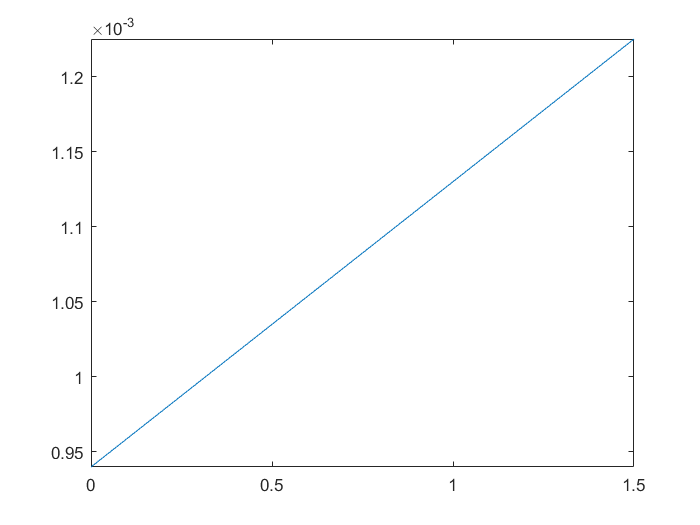

clear all
close all
m=1.9*10^-4;q=0.94*10^-3;
stdvoltaggi=9e-8;randomError=6e-7;
finestra=0.00005;
f=@(x) m*x+q;
fplot(f,[0 1.5])

z=linspace(0.01,1.5,20);
voltaggi=[];
pesi=[];
for e=z
    for i=1:20
        voltaggi=[voltaggi normrnd(f(e)+rand()*randomError,stdvoltaggi)];
        pesi=[pesi e];
    end
end





N=20000;
pend=[];
offset=[];
numeri=[];
for i=1:N
    pesi=[];
    for e=z
        for i=1:20
            
            pesi=[pesi e-(rand()*finestra-finestra/2)];
        end
    end
    polinomio=polyfit(pesi',voltaggi',1);
    pend=[pend polinomio(1)];
    offset=[offset polinomio(2)];
end
stdpend=std(pend)

stdpend = 3.0264e-10

stdoffset=std(offset)

stdoffset = 2.6589e-10

meanoff=mean(offset)

meanoff = 9.4024e-04

meanpend=mean(pend)

meanpend = 1.9005e-04

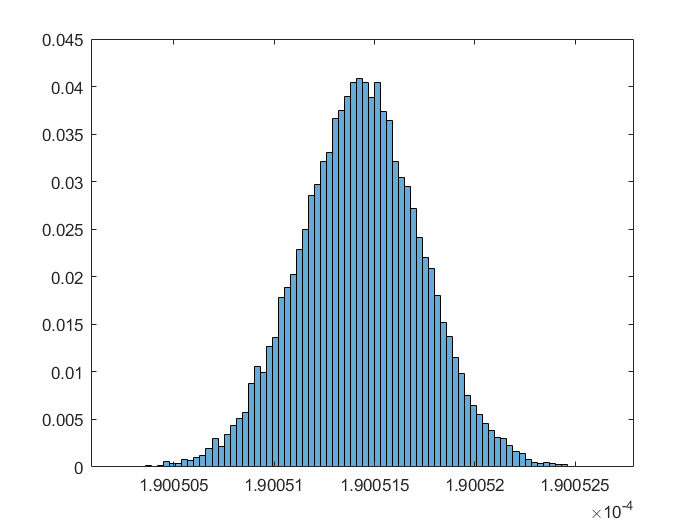

histogram(pend,'Normalization','probability')

histogram(pend,'Normalization','probability')

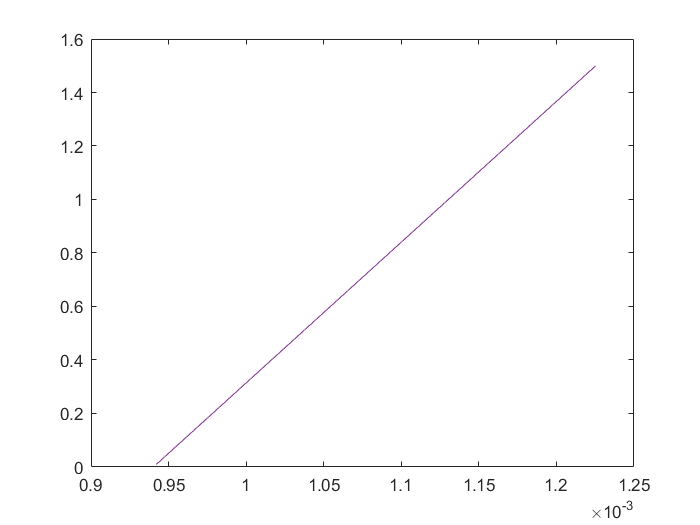

figure
pmax=[meanpend+stdpend*2 meanoff+stdoffset*2];
pmin=[meanpend-stdpend*2 meanoff-stdoffset*2];
ppendmax=[meanpend+stdpend*2 meanoff-stdoffset*2];
poffmax=[meanpend-stdpend*2 meanoff+stdoffset*2];
ymax=polyval(pmax,pesi);
ymin=polyval(pmin,pesi);
ypmax=polyval(ppendmax,pesi);
yomax=polyval(poffmax,pesi);
plot(ymax,pesi)
hold on
plot(ymin,pesi)
plot(ypmax,pesi)
plot(yomax,pesi)

max_mass=1.5;
max_err=((meanpend+stdpend)*max_mass-(meanpend-stdpend)*max_mass+stdoffset*2)/2

max_err = 7.1984e-10